# Battery Prognostic Experiments

polyval(Q_coef, 298)


load 'Q_coef.mat';
% cycle = find(x>=350, 1, 'first'); % not needed
cycle = 317;
polyval(Q_coef, 298)

# Prognostics Experiment

warning('off','MATLAB:polyfit:RepeatedPointsOrRescale');
load batteryParams.mat;
load ukfBatteryParams.mat;
global batteryParams;

load Q_coef;

k       = 1600; % number of cycles
v{k,1}  = []; % preallocate space
z{k,1}  = [];
c{k,1}  = [];
t{k,1}  = [];
%R0a     = zeros(k,1);
Qa      = zeros(k+1,1);
preds   = Qa;
preds1  = Qa;
%R0_orig = batteryParams.R0; % 0.001136807670048
Q_orig  = 3.8712; % 3.8
%R0a(1)  = batteryParams.R0; % initialize param vals
Qa(1)   = batteryParams.Q;
Qe      = Qa;
time    = 0.0;
eol     = 298; %cycles, 3.1v
rul     = eol;

maintWarn = 0;
maintNotice = false;
failWarn = 0;
failNotice = false;

maintThresh = 3.48;
failThresh  = 3.0922;

maintFlag = false;
failFlag  = false;

tic
for i = 2:k+1
    current = normrnd(4,1);
    simout = sim('../batteryMine');
    v{i-1} = simout.voltage_hat.Data;
    z{i-1} = simout.soc_hat.Data;
    c{i-1} = current;
    t{i-1} = simout.tout(end);
    time   = time + simout.tout(end);
    rul    = rul - 1;
    
    batteryParams.Q  = polyval(Q_coef, i);
    
    Qa(i)  = batteryParams.Q;
    Qe(i) = normrnd(Qa(i), .03);
       
    save('batteryParams.mat', 'batteryParams');
   
    if i >= 20
        x = ((i-19):1:i)';
        q_poly = polyfit(x, smoothdata(Qe((i-19):i), 'rlowess', 5), 1);
 
        q_pred = polyval(q_poly, i+5);
        preds1(i) = q_pred;
        
        q_pred = polyval(q_poly, i+20);
        
        if ~maintFlag && q_pred <= maintThresh
            maintFlag = true;
            maintWarn = i;
            disp(["Maintenance threshold will be reached at cycle: "  num2str(i+20)  "."]);
            disp(["Cumulative flight hours: "  num2str(time/60/60)]); 
        end
        
        if ~maintNotice && Qe(i) >= .985*maintThresh && Qe(i) <= 1.015*maintThresh
            maintNotice = true;
            disp(["Maintenance Required. Current cycle: " num2str(i)]);
            disp(["Cumulative flight hours: "  num2str(time/60/60)]);
        end
        
        if ~failFlag && q_pred <= failThresh
            failFlag = true;
            failWarn = i;
            disp(["Failure threshold will be reached at cycle: "  num2str(i+20)  "."]);
            disp(["Cumulative flight hours: "  num2str(time/60/60)]); 
        end
        
        if ~failNotice && Qe(i) >= .995*failThresh && Qe(i) <= 1.015*failThresh
            failNotice = true;
            disp(["Estimated failure is reached. Current cycle: " num2str(i)]);
            disp(["Cumulative flight hours: "  num2str(time/60/60)]);
        end
        
        if Qa(i) <= failThresh
            disp(["Actual failure is reached. Current cycle: " num2str(i)]);
            disp(["Cumulative flight hours: "  num2str(time/60/60)]);
            break
        end
    end
end
toc

    "Maintenance threshold will be reached at …"    "208"    "."



    "Cumulative flight hours: "    "144.6972"



    "Maintenance Required. Current cycle: "    "173"



    "Cumulative flight hours: "    "148.7981"



    "Failure threshold will be reached at cycl…"    "298"    "."



    "Cumulative flight hours: "    "214.9753"



    "Estimated failure is reached. Current cycle: "    "277"



    "Cumulative flight hours: "    "228.8944"



    "Actual failure is reached. Current cycle: "    "300"



    "Cumulative flight hours: "    "245.3819"



pgon = polyshape([failWarn failWarn eol eol], [Qa(failWarn)+.03 Qa(failWarn)-.03 Qa(eol)-.03 Qa(eol)+.03]);

Elapsed time is 1127.930289 seconds.


simResults.Qe    = Qe(1:eol);
simResults.preds = preds(1:eol);
simResults.Qa    = Qa(1:eol);
simResults.pgon  = pgon;
simResults.eol   = eol;
simResults.v     = v;
simResults.z     = z;

simResults.maintWarn   = maintWarn;
simResults.failWarn    = failWarn;
simResults.maintThresh = maintThresh;
simResults.failThresh  = failThresh;

batteryParams.Q  = Q_orig;
save('simResults.mat', "simResults");
save('batteryParams.mat', 'batteryParams');


f1 = figure(1); clf;
hold on;
% y = zeros(eol-1,1);
% for i = 1:eol-1
%     y = normrnd(Qa, .07);
% end
% plot(y, 'c.');
plot(Qe(1:eol), 'c.');
plot([20:1:eol]',smoothdata(preds1(20:eol), 'movmean', 10), 'linew', 2);
plot(Qa(1:eol), 'b', 'linew', 2);
pgon = polyshape([failWarn failWarn eol eol], [Qa(failWarn)+.03 Qa(failWarn)-.03 Qa(eol)-.03 Qa(eol)+.03]);
plot(pgon, 'FaceColor', 'yellow', 'FaceAlpha', .79, 'EdgeColor', 'none');
plot(maintWarn, Qa(maintWarn), 'ko', 'linew', 3);
plot(failWarn, Qa(failWarn), 'mo', 'linew', 2);
plot(failWarn+40, Qa(failWarn+40), '*', 'MarkerSize', 12);
plot(eol, Qa(eol), 'ro', 'linew', 2);
hold off;
%set(get(get(s, 'Annotation'), 'LegendInformation'), 'IconDisplayStyle', 'off');
title("Battery Capacitance Degradation");
xlabel("Cycle Number");
ylabel("Capacitance (A)");
ylim([2.5 4]);
legend(["Capacitance Samples", "Capacitance Estimate", "Actual Capacitance", "Prediction Horizon", "Maintenance Warning", "Failure Warning", "Estimated EOL", "EOL"], 'location', 'southwest');



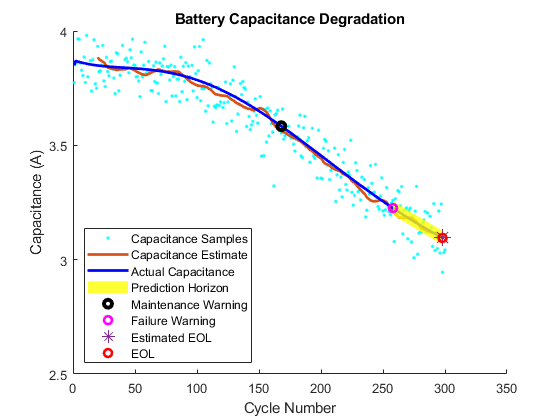

f2 = figure(2); clf;

hold on;
plot(Qa(1:eol), 'g', 'linew', 2);
pgon = polyshape([failWarn failWarn eol eol], [Qa(failWarn)+.03 Qa(failWarn)-.03 Qa(eol)-.03 Qa(eol)+.03]);
plot(pgon, 'FaceColor', 'yellow', 'FaceAlpha', .79, 'EdgeColor', 'none');
plot(maintWarn, Qa(maintWarn), 'bo', 'linew', 2);
plot(failWarn, Qa(failWarn), 'mo', 'linew', 2);
plot(eol, Qa(eol), 'ro', 'linew', 2);
hold off;
title("Battery Capacitance Degradation");
xlabel("Cycle Number");
ylabel("Capacitance (A)");
ylim([2.5 4]);
legend(["Capacitance Estimate", "Prediction Horizon", "Maintenance Warning", "Failure Warning", "EOL"], 'location', 'southeast');


f3  = figure(3); clf;
f3.Position = [0 0 1200 800];
hold on;
plot(smoothdata(v{1}, 'movmean', 500));
plot(smoothdata(v{167}, 'movmean', 500));
plot(smoothdata(v{167*2}, 'movmean', 500));
plot(smoothdata(v{167*3}, 'movmean', 500));
plot(smoothdata(v{167*4}, 'movmean', 500));
plot(smoothdata(v{167*5}, 'movmean', 500));
plot(smoothdata(v{167*6}, 'movmean', 500));
plot(smoothdata(v{167*7}, 'movmean', 500));
%plot(smoothdata(v{1341}, 'movmean', 500));
hold off;
title("Voltage Curves");
ylabel('Voltage');
xlabel('Run Time (s)');
%legend([['nominal, Q: ' num2str(Q_orig)], ['Q: ' num2str(Qa)] ])
ylim([3 4.5]);


f4 = figure(4); clf;
hold on;
plot(z{1});
for i = 1:8
    plot(z{i*150});
end
hold off;
title("SOC");

f5 = figure(5); clf;
plot(Qa);
title("capacitance");

f5 = figure(5); clf;
x = linspace(1,500,168);
y = Q_Experimental;
%p = polyfit(x,y,6);
y1 = polyval(Q_coef, x);
f2 = figure(2); clf;
hold on;
plot(x, Q_Experimental, 'b.');
plot(x, y1, 'linew', 2);
hold off;
ylim([ 2.5 4]);
title("Capacitance Degredation Model");
ylabel("Capacitance (Q)");
xlabel("Cycle No.");
legend(["Experimental Data", "Extrapolated Curve"])

a = 1; % amplitude
b = .01; % steepness
c = 200; % x axis shift

x = linspace(0,600,600);

sig = a ./ (1+exp(-b*(x-c)));
sig = interp1([.11 1], [.0112 .016], sig);

f3 = figure(3); clf;
hold on;
plot(x, sig, 'linew', 3);
plot([0 0], get(gca, 'ylim'), 'k--');
hold off;
title("Resistance Degradation Model");
ylabel("R0 Value ({\Omega})");
xlabel("cycle number");
sig(1)
